x_axis = linspace(1,27,27),

x_axis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27


y_over = [0.0800000000000000	0.170000000000000	0.300000000000000	0.480000000000000	1	2.75000000000000	4.01000000000000	8	13.2000000000000	16	19	21	25	21	24	36	58	82	83	97	96	100	110	122	134	134	134]

y_over =     0.0800    0.1700    0.3000    0.4800    1.0000    2.7500    4.0100    8.0000   13.2000   16.0000   19.0000   21.0000   25.0000   21.0000   24.0000   36.0000   58.0000   82.0000   83.0000   97.0000   96.0000  100.0000  110.0000  122.0000  134.0000  134.0000  134.0000


% 对趋势下降的点进行移除
idx = find(diff(y_over) <= 0);
y_cleaned = y_over;
y_cleaned(idx) = NaN;

% 线性插值来填补缺失数据，但只对 NaN 的位置插值
nan_idx = find(isnan(y_cleaned));
x = setdiff(1:length(y_cleaned), nan_idx);
y_cleaned(nan_idx) = interp1(x, y_cleaned(x), nan_idx, 'linear');

% 计算梯度
y_grad = gradient(y_cleaned);

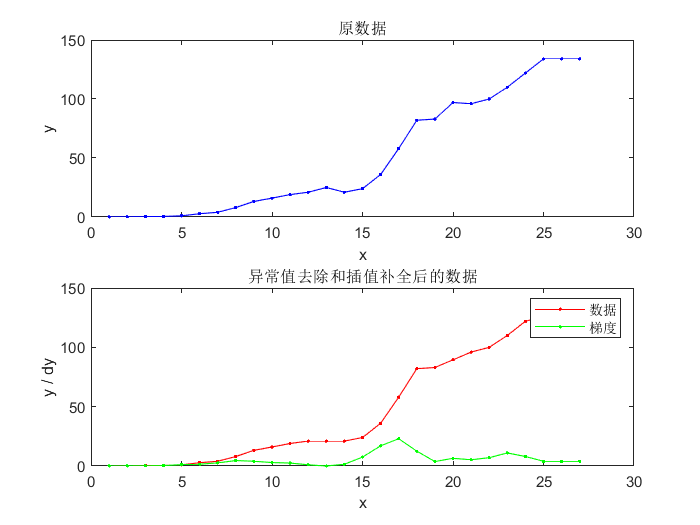

% 绘制原数据
figure;
subplot(2,1,1);
plot(x_axis, y_over, 'b.-');
title('原数据');
xlabel('x');
ylabel('y');

% 绘制异常值处理和插值后的数据
subplot(2,1,2);
plot(x_axis, y_cleaned, 'r.-', x_axis, y_grad, 'g.-');
title('异常值去除和插值补全后的数据');xlabel('x');
ylabel('y / dy');
legend('数据', '梯度');

Y=y_cleaned'

Y =     0.0800
    0.1700
    0.3000
    0.4800
    1.0000
    2.7500
    4.0100
    8.0000
   13.2000
   16.0000
